## 2 DOF Rigid Joint Robot Manipulator

Lagrange-Euler Dynamic Model of Planar 2DOF Rigid Joint Robot

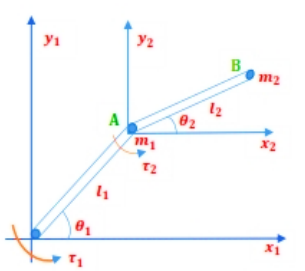

### Parameters

- Li: length of link i (i=1,2)

- Lci: distance to centre of centre of gravity of link i (i=1,2)

- mi: mass i (i=1,2)

- Ii: moment of inertia at z axis of link i (i=1,2)

- Bi: viscous damping coefficient of link (i=1,2)

### Parameters Value

- L1 = 0.343 m (User Manual)

- L2 = 0.267 m (User Manual)

- Lc1 = 0.2 m (Veltman Thesis)                         0.1590 m (Electrical School)

- Lc2 = 0.25 m (Veltman Thesis)                       0.0550 m (Electrical School)

- m1 = 0.5 kg (Veltman Thesis)                         1.51 kg (Electrical School)

- m2 = 1 kg (Veltman Thesis)                            0.87326 kg (Electrical School)

- l1 = 0.01 kgm^2 (Veltman Thesis)                   0.0392 kgm^2 (Electrical School)

- l2 = 0.01 kgm^2 (Veltman Thesis)                   0.0081 kgm^2 (Electrical School)

- B1 = 0.070364 Nms/rad (Electrical School)    0.038 Nms/rad (Veltman Thesis)

- B2 = 0.028211 Nms/rad (Electrical School)    0.03 Nms/rad (Veltman Thesis)

clear;
syms L1 L2 Lc1 Lc2 m1 m2 I1 I2 B1 B2 theta1(t) theta2(t)
syms TH1 TH2 TH1D TH2D TH1DD TH2DD

tmp = [theta1,          TH1;
       diff(theta1,t),  TH1D;
       diff(theta1,t,2),TH1DD;
       theta2,          TH2;
       diff(theta2,t),  TH2D;
       diff(theta2,t,2),TH2DD];
   
tmp = formula(tmp);
actual = tmp(:,1);
holder = tmp(:,2);

x1 = Lc1*cos(theta1);
y1 = Lc1*sin(theta1);

x2 = L1*cos(theta1)+Lc2*cos(theta1+theta2);
y2 = L1*sin(theta1)+Lc2*sin(theta1+theta2);


## Kinetic Energy

### Translational Kinetic Energy

KE_trans1 = (1/2)*m1*(diff(x1,t)^2+diff(y1,t)^2);
KE_trans1 = simplify(KE_trans1)

$$KE\_trans1(t) = \frac{{{\mathrm{Lc}}_{1}}^{2}\,m_{1}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{2}$$

KE_trans1 = subs(KE_trans1,actual,holder);

KE_trans2 = (1/2)*m2*(diff(x2,t)^2+diff(y2,t)^2);
KE_trans2 = simplify(KE_trans2)

$$KE\_trans2(t) = \begin{array}{l} \frac{m_{2}\,\left({L_{1}}^{2}\,\sigma_{1}+{{\mathrm{Lc}}_{2}}^{2}\,\sigma_{1}+{{\mathrm{Lc}}_{2}}^{2}\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}+2\,{{\mathrm{Lc}}_{2}}^{2}\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)+2\,L_{1}\,{\mathrm{Lc}}_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\sigma_{1}+2\,L_{1}\,{\mathrm{Lc}}_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}{2}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2} \end{array}$$

la = latex(KE_trans2)

la = '\frac{m_{2}\,\left({L_{1}}^2\,{\left(\frac{\partial }{\partial t} \theta _{1}\left(t\right)\right)}^2+{\mathrm{Lc}_{2}}^2\,{\left(\frac{\partial }{\partial t} \theta _{1}\left(t\right)\right)}^2+{\mathrm{Lc}_{2}}^2\,{\left(\frac{\partial }{\partial t} \theta _{2}\left(t\right)\right)}^2+2\,{\mathrm{Lc}_{2}}^2\,\frac{\partial }{\partial t} \theta _{2}\left(t\right)\,\frac{\partial }{\partial t} \theta _{1}\left(t\right)+2\,L_{1}\,\mathrm{Lc}_{2}\,\cos\left(\theta _{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \theta _{1}\left(t\right)\right)}^2+2\,L_{1}\,\mathrm{Lc}_{2}\,\cos\left(\theta _{2}\left(t\right)\right)\,\frac{\partial }{\partial t} \theta _{2}\left(t\right)\,\frac{\partial }{\partial t} \theta _{1}\left(t\right)\right)}{2}'

KE_trans2 = subs(KE_trans2,actual,holder);


### Rotational Kinetic Energy

KE_rot1 = (1/2)*I1*(diff(theta1,t))^2;
KE_rot1 = subs(KE_rot1,actual,holder);
KE_rot2 = (1/2)*I2*(diff(theta1,t)+diff(theta2,t))^2;
KE_rot2 = subs(KE_rot2,actual,holder);

### Total Kinetic Energy

KE1 = KE_trans1+KE_rot1

$$KE1(t) = \frac{m_{1}\,{{\mathrm{Lc}}_{1}}^{2}\,{\mathrm{TH1D}}^{2}}{2}+\frac{I_{1}\,{\mathrm{TH1D}}^{2}}{2}$$

KE2 = KE_trans2+KE_rot2

$$KE2(t) = \frac{I_{2}\,{\left(\mathrm{TH1D}+\mathrm{TH2D}\right)}^{2}}{2}+\frac{m_{2}\,\left({L_{1}}^{2}\,{\mathrm{TH1D}}^{2}+2\,\cos\left({\mathrm{TH}}_{2}\right)\,L_{1}\,{\mathrm{Lc}}_{2}\,{\mathrm{TH1D}}^{2}+2\,\cos\left({\mathrm{TH}}_{2}\right)\,L_{1}\,{\mathrm{Lc}}_{2}\,\mathrm{TH1D}\,\mathrm{TH2D}+{{\mathrm{Lc}}_{2}}^{2}\,{\mathrm{TH1D}}^{2}+2\,{{\mathrm{Lc}}_{2}}^{2}\,\mathrm{TH1D}\,\mathrm{TH2D}+{{\mathrm{Lc}}_{2}}^{2}\,{\mathrm{TH2D}}^{2}\right)}{2}$$

## Potential Energy

- Since it is planar, there will be no gravity acting on it

- PE = 0

PE1=0;
PE2=0;

## The Lagrangian


$$L\left(\theta ,\theta^˙ \right)=K\left(\theta ,\theta^˙ \right)-P\left(\theta \right)$$


Lag1=KE1-PE1;
Lag2=KE2-PE2;
L=Lag1+Lag2;

$$L(t) = \frac{I_{2}\,{\left(\mathrm{TH1D}+\mathrm{TH2D}\right)}^{2}}{2}+\frac{I_{1}\,{\mathrm{TH1D}}^{2}}{2}+\frac{m_{2}\,\left({L_{1}}^{2}\,{\mathrm{TH1D}}^{2}+2\,\cos\left({\mathrm{TH}}_{2}\right)\,L_{1}\,{\mathrm{Lc}}_{2}\,{\mathrm{TH1D}}^{2}+2\,\cos\left({\mathrm{TH}}_{2}\right)\,L_{1}\,{\mathrm{Lc}}_{2}\,\mathrm{TH1D}\,\mathrm{TH2D}+{{\mathrm{Lc}}_{2}}^{2}\,{\mathrm{TH1D}}^{2}+2\,{{\mathrm{Lc}}_{2}}^{2}\,\mathrm{TH1D}\,\mathrm{TH2D}+{{\mathrm{Lc}}_{2}}^{2}\,{\mathrm{TH2D}}^{2}\right)}{2}+\frac{{{\mathrm{Lc}}_{1}}^{2}\,{\mathrm{TH1D}}^{2}\,m_{1}}{2}$$

## Equation of motion


$$\tau =\frac{d}{\textrm{dt}}\frac{\partial }{\partial \theta^˙ }L-\frac{\partial }{\partial \theta }L$$


h0=diff(L,TH1D);

$$h0(t) = \mathrm{TH1D}\,m_{1}\,{{\mathrm{Lc}}_{1}}^{2}+\frac{m_{2}\,\left(2\,{L_{1}}^{2}\,\mathrm{TH1D}+2\,{{\mathrm{Lc}}_{2}}^{2}\,\mathrm{TH1D}+2\,{{\mathrm{Lc}}_{2}}^{2}\,\mathrm{TH2D}+4\,L_{1}\,{\mathrm{Lc}}_{2}\,\mathrm{TH1D}\,\cos\left({\mathrm{TH}}_{2}\right)+2\,L_{1}\,{\mathrm{Lc}}_{2}\,\mathrm{TH2D}\,\cos\left({\mathrm{TH}}_{2}\right)\right)}{2}+\frac{I_{2}\,\left(2\,\mathrm{TH1D}+2\,\mathrm{TH2D}\right)}{2}+I_{1}\,\mathrm{TH1D}$$

h0=subs(h0,holder,actual);
h1 = diff(L,TH1);
h1 = subs(h1,holder,actual);
tau1=diff(h0,t)-h1;
tau1 = simplify(tau1)

$$tau1(t) = \begin{array}{l} I_{1}\,\sigma_{1}+I_{2}\,\sigma_{1}+I_{2}\,\sigma_{2}+{L_{1}}^{2}\,m_{2}\,\sigma_{1}+{{\mathrm{Lc}}_{1}}^{2}\,m_{1}\,\sigma_{1}+{{\mathrm{Lc}}_{2}}^{2}\,m_{2}\,\sigma_{1}+{{\mathrm{Lc}}_{2}}^{2}\,m_{2}\,\sigma_{2}-L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}+2\,L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\sigma_{1}+L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\sigma_{2}-2\,L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right) \end{array}$$


h2=diff(L,TH2D);
h2=subs(h2,holder,actual);
h3 = diff(L,TH2);
h3 = subs(h3,holder,actual);
tau2=diff(h2,t)-h3;
tau2 = simplify(tau2) 

$$tau2(t) = I_{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)+I_{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)+{{\mathrm{Lc}}_{2}}^{2}\,m_{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)+{{\mathrm{Lc}}_{2}}^{2}\,m_{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)+L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)$$

tau2 = subs(tau2,actual,holder);


### Write in the form of


$$M\left(\theta \right)\theta^¨ +C\left(\theta ,\theta^˙ \right)\theta^˙ +G\left(\theta \right)+f_v \left(\theta^˙ \right)=\tau$$


- fv is the viscous damping coefficient 

M11 = I2+I1+m2*((L1^2)+(Lc2^2)+2*L1*Lc2*cos(theta2))+m1*(Lc1^2);
M12 = I2+m2*(Lc2^2)+L1*Lc2*m2*cos(theta2);
M21 = M12;
M22 = I2+m2*(Lc2^2);

M = [M11 M12;
     M21 M22]

$$M(t) = \left(\begin{array}{cc} m_{1}\,{{\mathrm{Lc}}_{1}}^{2}+I_{1}+I_{2}+m_{2}\,\left({L_{1}}^{2}+2\,\cos\left(\theta_{2}\left(t\right)\right)\,L_{1}\,{\mathrm{Lc}}_{2}+{{\mathrm{Lc}}_{2}}^{2}\right) & m_{2}\,{{\mathrm{Lc}}_{2}}^{2}+L_{1}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,{\mathrm{Lc}}_{2}+I_{2}\\ m_{2}\,{{\mathrm{Lc}}_{2}}^{2}+L_{1}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,{\mathrm{Lc}}_{2}+I_{2} & m_{2}\,{{\mathrm{Lc}}_{2}}^{2}+I_{2} \end{array}\right)$$

 
C11 = -m2*L1*Lc2*sin(theta2)*diff(theta2,t);
C12 = -m2*L1*Lc2*sin(theta2)*diff(theta2,t)-m2*L1*Lc2*sin(theta2)*diff(theta1,t);
C21 = m2*L1*Lc2*sin(theta2)*diff(theta1,t);
C22 = 0;

C = [C11 C12;
     C21 C22]

$$C(t) = \left(\begin{array}{cc} -L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right) & -L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)-L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right) & 0 \end{array}\right)$$


fv = [B1 0;
      0  B2]

$$fv = \left(\begin{array}{cc} B_{1} & 0\\ 0 & B_{2} \end{array}\right)$$

Citations

- robotacadamy